# **Project**

Bhavisha Chafekar - 2021200016

Sahil Kurkure - 2021200062

Saket Lad - 2021200063

### **Problem Statement :**

- Compare eye patterns and PSD  of a QPSK and 8-PSK  modulated signal followed by raised cosine filtering. Consider SNR of AWGN channel between 2 to 20 db

### **Software Used :**

- Matlab R2023a

### Results** :**

#### **Definations**

%Definations

%Genearte Data
length = input('Length of the data : ');
x = randi([0 1],length,1);
Fs=1000;

% To Perform n-fft to obtain the equivalent power of the data
nfft = 2^nextpow2(length); 
frequencies = linspace(0, Fs, nfft);

sps_QPSK=4;
sps_8PSK=8;

%SNR value
SNR_DB = input('Noise (in dB) : ');

#### **QPSK**

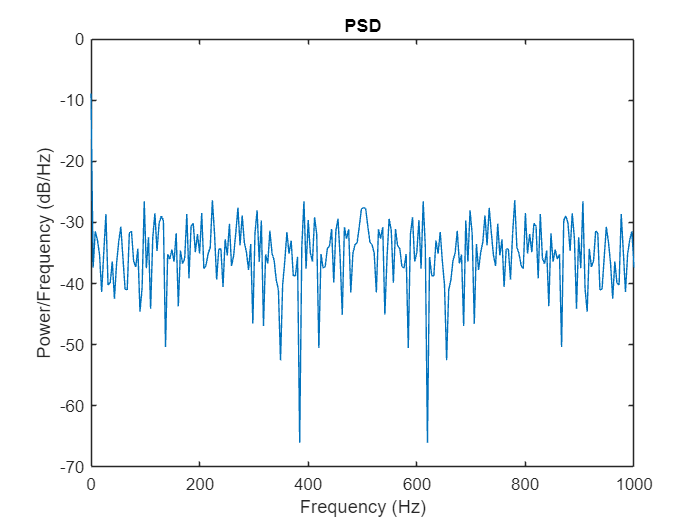

%QPSK

%Apply QPSK Modulation 
QPSK_modsig = pskmod(x,sps_QPSK);

%PSD
QPSK_PSD = abs(fft(QPSK_modsig, nfft)).^2 / length / Fs; 
plot(frequencies, 10*log10(QPSK_PSD)); 
title('PSD'); 
xlabel('Frequency (Hz)'); 
ylabel('Power/Frequency (dB/Hz)');

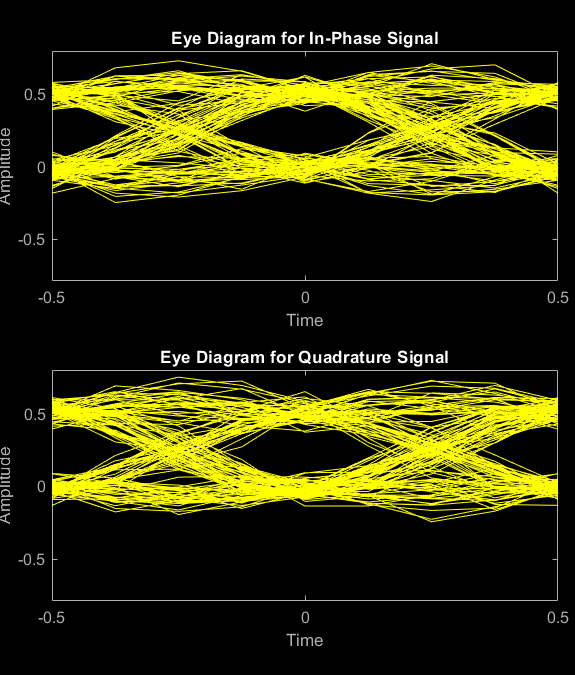

h =   Figure (Eye Diagram) with properties:

      Number: 10
        Name: 'Eye Diagram'
       Color: [0 0 0]
    Position: [258 -28 460 540]
       Units: 'pixels'

  Show all properties



%Apply the RCF Transmit filter
txfilter = comm.RaisedCosineTransmitFilter('OutputSamplesPerSymbol',sps_QPSK);
QPSK_RCF_modsig = txfilter(QPSK_modsig);

%Add noise
QPSK_RCF_Nosie_modsig=awgn(QPSK_RCF_modsig,SNR_DB,'measured');
%Eyedigram
h=eyediagram(QPSK_RCF_Nosie_modsig,2*sps_QPSK)

eyediagram(QPSK_RCF_Nosie_modsig,2*sps_QPSK)

#### **8-PSK**

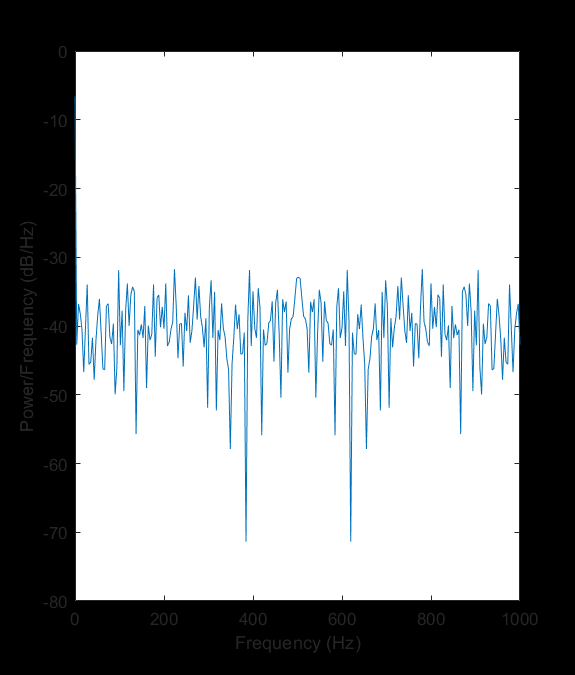

%8-PSK

%Apply QPSK Modulation 
PSK_8_modsig = pskmod(x,sps_8PSK);

%PSD
PSK_8_PSD = abs(fft(PSK_8_modsig, nfft)).^2 / length / Fs; 
plot(frequencies, 10*log10(PSK_8_PSD)); 
title('PSD'); 
xlabel('Frequency (Hz)'); 
ylabel('Power/Frequency (dB/Hz)');

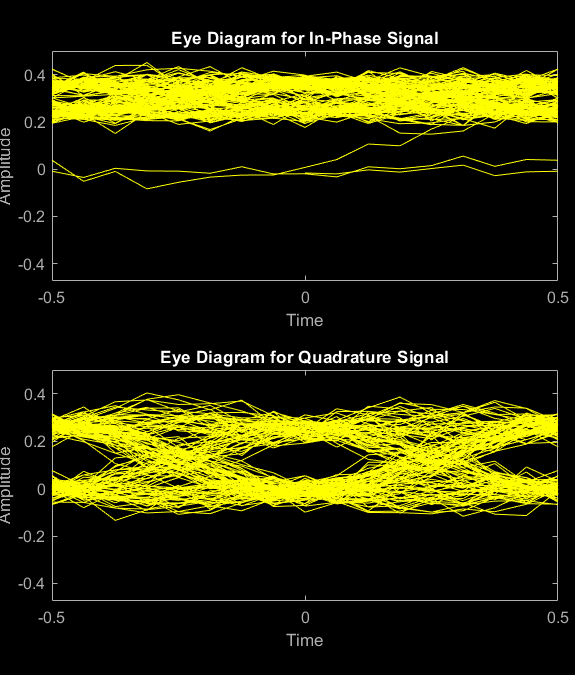


%Apply the RCF Transmit filter
txfilter = comm.RaisedCosineTransmitFilter('OutputSamplesPerSymbol',sps_8PSK);
PSK_8_RCF_modsig = txfilter(PSK_8_modsig);

%Add noise
PSK_8_RCF_Nosie_modsig=awgn(PSK_8_RCF_modsig,SNR_DB,'measured');

%Eyedigram
eyediagram(PSK_8_RCF_Nosie_modsig,2*sps_8PSK)